nt = 2010;
dt = 0.5; % s
t = (0:nt-1)*dt;
x = cos(2*pi*0.02*t); % Dummy signal of length and freq similar to kidney TGF data

### Create a filter bank - a set of scaled wavelets

fb = cwtfilterbank("SamplingFrequency",1/dt, ...
    "SignalLength",nt, ...
    "FrequencyLimits",[0.007, 0.1], ...
    "TimeBandwidth",15) % Make wavelets narrow (hence, fewer oscillations in the wavelet)

fb =   cwtfilterbank with properties:

      VoicesPerOctave: 10
              Wavelet: "Morse"
    SamplingFrequency: 2
       SamplingPeriod: []
         PeriodLimits: []
         SignalLength: 2010
      FrequencyLimits: [0.0070 0.1000]
        TimeBandwidth: 15
    WaveletParameters: []
             Boundary: "reflection"


### Show Wavelet magnitude in frequency space (their Magnitude spectra)

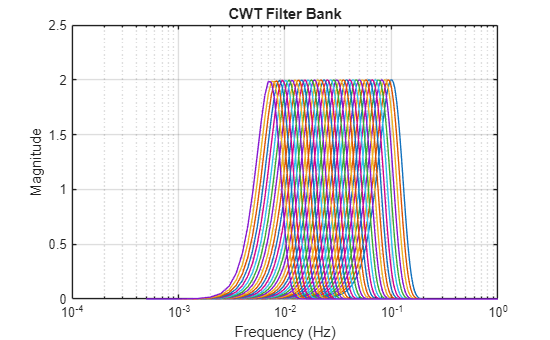

fb.freqz()
xscale('log')

### Show Two wavelets from the bank

wavefuns = fb.wavelets;
scales = fb.scales;

[~, idx1] = min(abs(scales-8));
[~, idx2] = min(abs(scales-25));

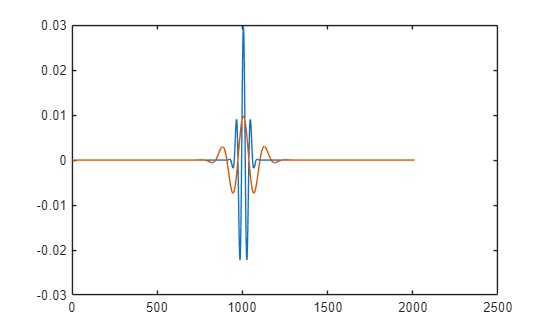

figure()
plot(real(wavefuns(idx1,:)))
hold on 
plot(real(wavefuns(idx2,:)))
hold off

### Plot synthetic data

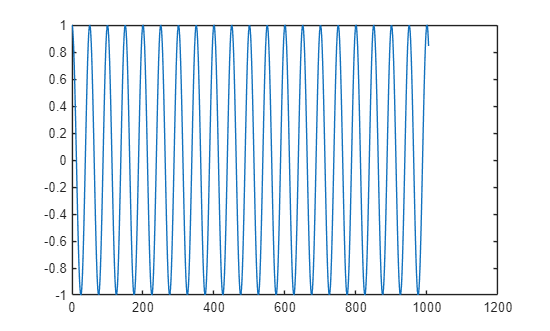

figure()
plot(t,x)

### Show Wavelet magnitude scalogram and scale-averaged spectrum

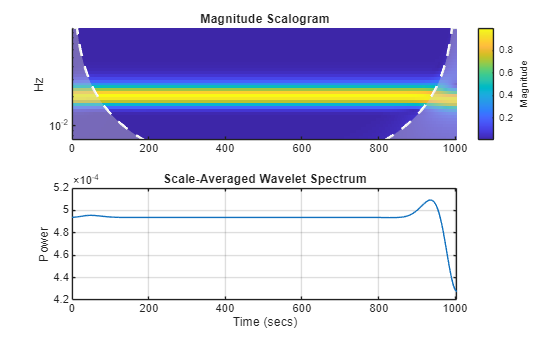

fb.scaleSpectrum(x, "Normalization","pdf", ...
    "SpectrumType","power", ...
    "FrequencyLimits",[0.015, 0.03])